# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_2_Data_Analysys

## Normalizing Data

This activity introduces **data normalization**, an essential preprocessing step that makes variables comparable by adjusting for differences in scale or location.

Normalization allows us to perform statistical analysis and modeling more effectively, especially when variables have different units or magnitudes.

In this Live Script, you will also learn how to **insert and use MATLAB Tasks**.

Tasks provide an interactive way to perform common data-analysis operations—such as normalization, fitting distributions, or cleaning missing values—without writing code manually.

You can insert a Task by selecting:

**Live Editor Tab → Task → Add Task → Normalize Data**.

Once added, the Task automatically generates MATLAB code that can be edited, executed, and reused in your scripts.

First import the data

% Import data from spreadsheet
Data = readtimetable("C:\Users\mdolf\OneDrive\Documents\Didattica 2026\MATLAB\Codes\Data\Data.xlsx", "RowTimes", "Date");

% Display results
Data

Data = 165×12 timetable
       Date         AAPL      MSFT      NVDA     GOOGL      GOOG      JPM        GS      HSBC      KO        PG       XOM      SHEL 
    ___________    ______    ______    ______    ______    ______    ______    ______    _____    _____    ______    ______    _____

    02-Jan-2025    243.85    418.58    138.31    189.43    190.63       240    574.97    48.68    61.84    165.98    107.31     63.1
    03-Jan-2025    243.36    423.35    144.47    191.79    193.13    243.28    580.13    49.07    61

Convert into a table

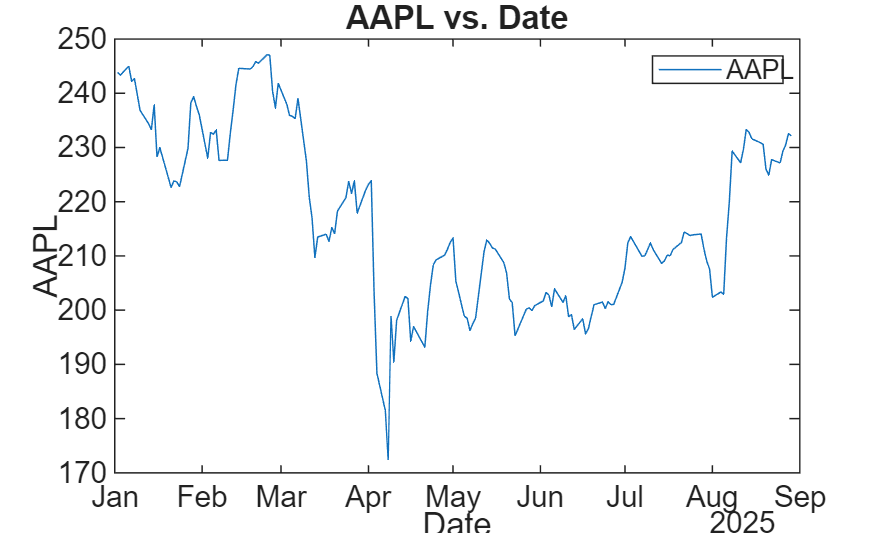

% Create plot of Data.Date and Data.AAPL
h = plot(Data,"Date","AAPL","DisplayName","AAPL");

% Add xlabel, ylabel, title, and legend
xlabel("Date")
ylabel("AAPL")
title("AAPL vs. Date")
legend

The Live Editor task uses the `normalize` function.

*Normalize data using a specified normalization method.*

`xNorm` `=` `normalize``(``x``)`

The following code normalizes the columns of a matrix using **z-scores**.

For a data matrix X (observations in rows, variables in columns), each column is standardized as


$$Z=\frac{X-mean(X)}{std(X)$$


where

- $mean(X)$is the column-wise mean, subtracted from each column,

- $std(X)$is the column-wise standard deviation, used to rescale each column.

After this transformation, each column of Z has mean 0 and standard deviation 1.

This way, the new matrix Z shows each value in terms of "how many standard deviations it is away from the mean''.

Z = zscore(X);

Optionally, MATLAB allows a **robust version**: each column is centered by its median and scaled by the **median absolute deviation (MAD)**, which reduces the influence of outliers.


$$Z=\frac{X-mean(X)}{MAD(X)$$


where $\[
{MAD}(X) = {median}\!\left( \,\big|X - {median}(X)\big| \,\right)
\]
$

**Median–IQR normalization** is a robust alternative to z-score normalization.

The median is the central value of a dataset when sorted. It measures the "typical" value and is not affected much by outliers.

The interquartile range (IQR) is the distance between the 75th percentile. It measures the spread of the middle 50% of the data:

Using these, each column of a data matrix can be normalized as


$$Z=\frac{X-mean(X)}{IQR(X)$$


This transformation centers the data around zero median and rescales it in units of IQR instead of standard deviation.

Center the mean of the columns in a matrix on zero.

`xNorm` `=` `normalize``(``x``,``"center"``,``"mean"``)`

Scale the columns of a matrix by the first element of each column.

`xNorm` `=` `normalize``(``x``,``"scale"``,``"first"``)`

Stretch or compress the data in each column of a matrix into a specified interval.

`xNorm` `=` `normalize``(``x``,``"range"``,``[``a` `b``])`

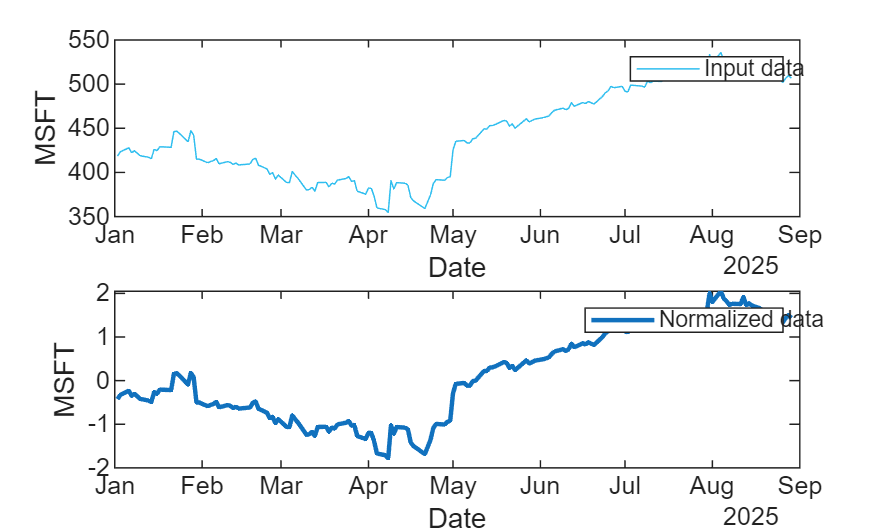

% Normalize Data
newTable = normalize(Data,"zscore","robust",DataVariables="MSFT");

% Display results
figure
tiledlayout(2,1);
nexttile
plot(Data.Date,Data.MSFT,SeriesIndex=6,DisplayName="Input data")
legend
ylabel("MSFT")
xlabel("Date")

nexttile
plot(Data.Date,newTable.MSFT,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Normalized data")
legend
ylabel("MSFT")
xlabel("Date")

set(gcf,NextPlot="new")